# Input-output function

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

## Part 0: Initialization

Specify the dataset to analyze

% We need to specify the prefix of the project we wish to analyze
Prefix = '2020-02-21-optoknirps_new_embryo5';

Variables depending on the data

- Start/Final frames

start_frame = 20;
final_frame = 124;
time_point_final = 6:1/6:42;

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['/Users/jiaxi.zhao/Dropbox/OptoDropbox/#analysis/202004 - perturbation analysis/with_export/figure/' Prefix];
% Make result path
ResultPath = ['/Users/jiaxi.zhao/Dropbox/OptoDropbox/#analysis/202004 - perturbation analysis/with_export/result/'];

mkdir(FigPath)

mkdir(ResultPath)


% Specify the position of DynamicsResults folder
DynamicsResultsFolder = '/Users/jiaxi.zhao/Dropbox/OptoDropbox';

Now, load all the data

% Now we'll load the CompiledParticles dataset
% This generates a string that gives the path to CompiledParticles
LoadParticlePath = [DynamicsResultsFolder '/' Prefix '/CompiledParticles.mat']; 
LoadNucleiPath = [DynamicsResultsFolder '/' Prefix '/' Prefix '_lin.mat'];
load(LoadParticlePath)
load(LoadNucleiPath)


## Part 2: Quality check on nuclei tracking

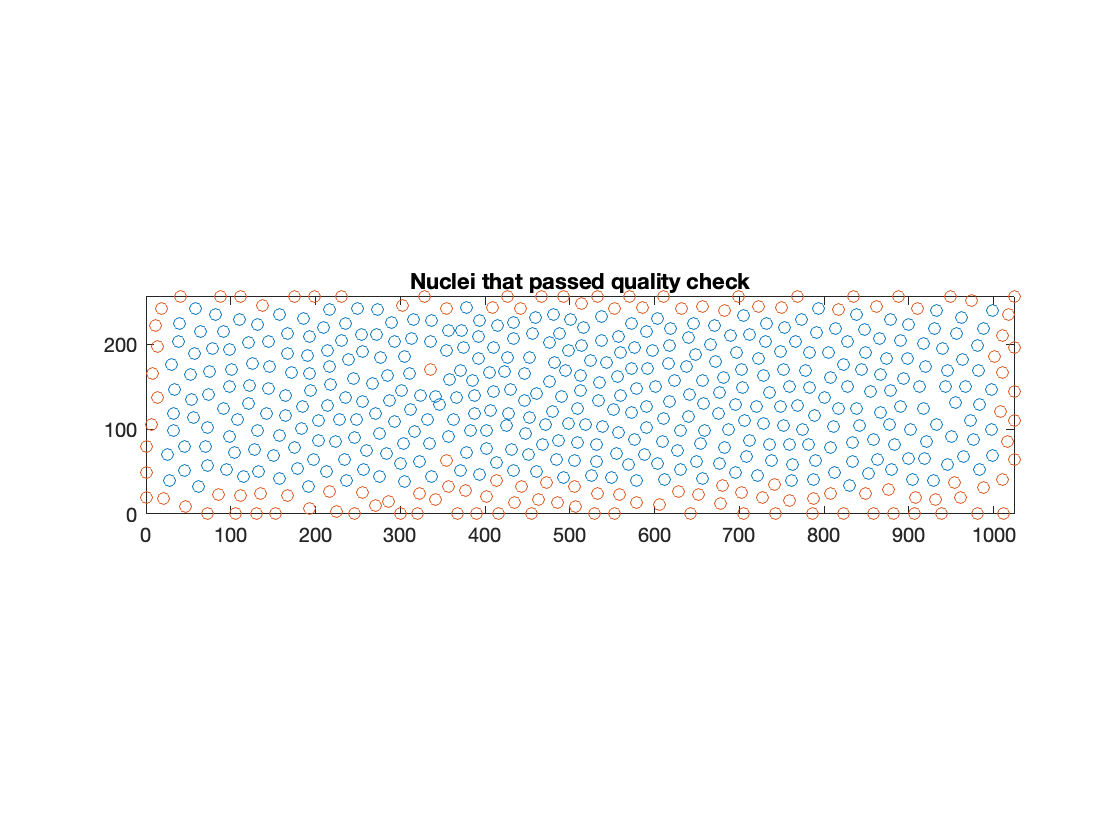

% Quality check and save the nuclei that passed the test
% Requires the nuclei to have continuous trace until lateral movement
X_pass = [];
Y_pass = [];

X_fail = [];
Y_fail = [];

sch_pass = [];

for i = 1:size(schnitzcells,2)
    index_s = find(schnitzcells(i).frames == start_frame);
    index_f = find(schnitzcells(i).frames == final_frame);
    fluo_temp = max(schnitzcells(i).Fluo(index_s:index_f,:),[],2);
    result = sum(isnan(fluo_temp));
    % quality check
    if ~isempty(index_s) && ~isempty(index_f) && (index_f-index_s == final_frame-start_frame)  ...
            && (result == 0)
        sch_pass = [sch_pass, i];
        X_pass = [X_pass, schnitzcells(i).cenx(index_s)];
        Y_pass = [Y_pass, schnitzcells(i).ceny(index_s)];
    else
        X_fail = [X_fail, schnitzcells(i).cenx(index_s)];
        Y_fail = [Y_fail, schnitzcells(i).ceny(index_s)];
    end
end
figure(1)
plot(X_pass,Y_pass,'o')
hold on
plot(X_fail,Y_fail,'o')
axis equal
xlim([0 1024])
ylim([0 256])
title('Nuclei that passed quality check')

## Part 3: Compile the schnitzcells together

% Initialize storage
processed_data(1).xcoord = [];
processed_data(1).ycoord = [];

processed_data(1).schnitznum = [];
processed_data(1).NuclearFluo = [];
processed_data(1).SpotFluo = [];

% Compile all the nuclei in each frame and assign basic info
for i = 1:length(sch_pass)
    sch_num = sch_pass(i);
    index_s = find(schnitzcells(sch_num).frames == start_frame);
    index_f = find(schnitzcells(sch_num).frames == final_frame);
    
    for j = index_s:index_f
        sch_now = sch_pass(i);
        frame_now = schnitzcells(sch_now).frames(j);
        x_coord = schnitzcells(sch_now).cenx(j);
        y_coord = schnitzcells(sch_now).ceny(j);
        fluo = max(schnitzcells(sch_now).Fluo(j,:));
        try
            processed_data(frame_now).xcoord = [processed_data(frame_now).xcoord, x_coord];
            processed_data(frame_now).ycoord = [processed_data(frame_now).ycoord, y_coord];
            processed_data(frame_now).schnitznum = [processed_data(frame_now).schnitznum, sch_now];
            processed_data(frame_now).SpotFluo = [processed_data(frame_now).SpotFluo, 0];
            processed_data(frame_now).NuclearFluo = [processed_data(frame_now).NuclearFluo fluo];  
        catch
            processed_data(frame_now).xcoord = x_coord;
            processed_data(frame_now).ycoord = y_coord;
            processed_data(frame_now).schnitznum = sch_now;
            processed_data(frame_now).SpotFluo = 0;
            processed_data(frame_now).NuclearFluo = fluo;
        end
    end
end

% Assign particle info to all the nuclei
for i = 1:size(CompiledParticles{1,1},2)
    schnitz_num = CompiledParticles{1,1}(i).schnitz;
    for j = 1:size(CompiledParticles{1,1}(i).Frame,2)
        frame = CompiledParticles{1,1}(i).Frame(j);
        if frame<=final_frame
            num = find(processed_data(frame).schnitznum==schnitz_num);
            processed_data(frame).SpotFluo(num) = CompiledParticles{1,1}(i).Fluo(j);
        end
    end
end


Let's try to plot the data

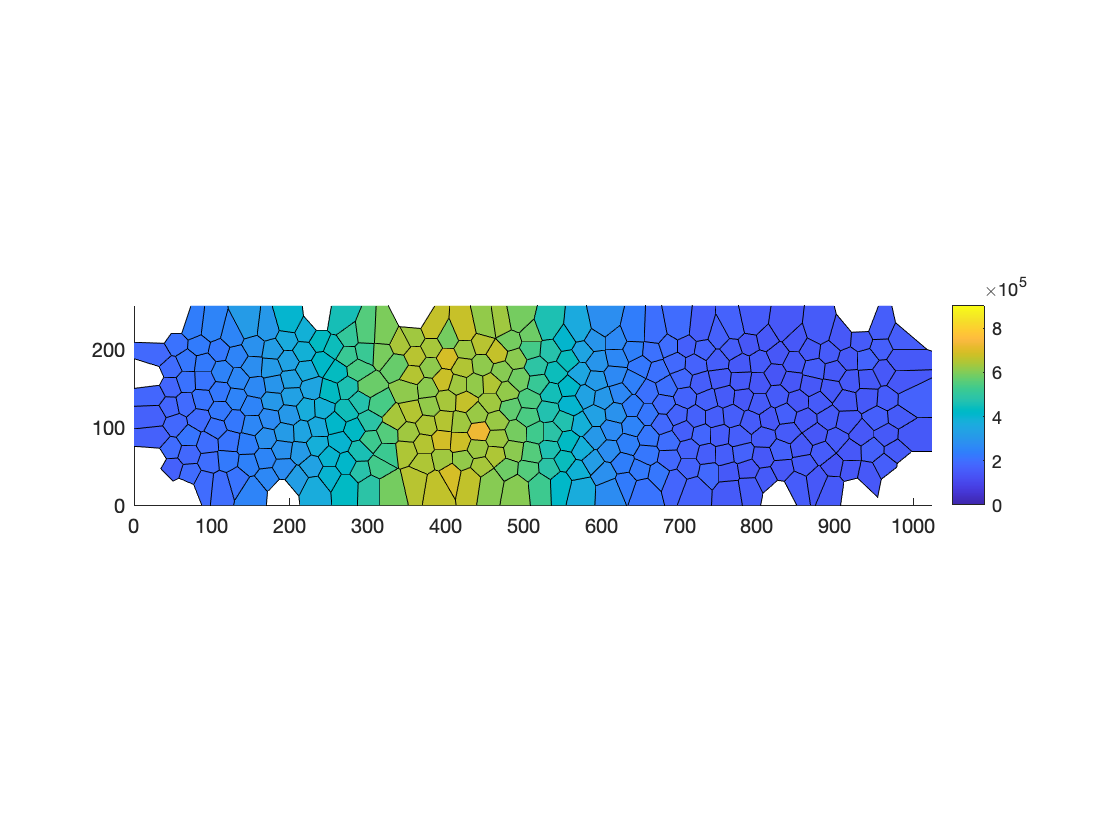

frame_plot = 100;

xpos = processed_data(frame_plot).xcoord;
ypos = processed_data(frame_plot).ycoord;

% try to plot and test a bit...
pts = [xpos' ypos'];

fig = figure(2);
[v,c] = voronoin(double(pts));

for i = 1:length(c)
    if all(c{i}~=1)
    x = v(c{i},1);
    y = v(c{i},2);
    %a = processed_data(frame_plot).SpotFluo(i);
    a = processed_data(frame_plot).NuclearFluo(i);
    patch(x,y,a);
    colorbar
    caxis([0 9E5])
    end
end

axis equal
xlim([0 1024])
ylim([0 256])

Now we can convert the format and store them into individual nuclei traces

% Convert the format: Store them into individual nuclei traces
nuclei_fluo_traces = zeros(length(sch_pass),final_frame);
spot_fluo_traces = zeros(length(sch_pass),final_frame);
x_pos = zeros(length(sch_pass),final_frame);
y_pos = zeros(length(sch_pass),final_frame);

for i = 1:length(sch_pass)
    for j = start_frame:final_frame
        nuclei_fluo_traces(i,j) = processed_data(j).NuclearFluo(i);
        spot_fluo_traces(i,j) = processed_data(j).SpotFluo(i);
        x_pos(i,j) = processed_data(j).xcoord(i);
        y_pos(i,j) = processed_data(j).ycoord(i);
    end
end

## Part 4: Process traces

% We would like to combine everything together and interpolate values
% Define time point to interpolate
x = ElapsedTime(1:final_frame);

nuclei_fluo_ins = zeros(length(sch_pass),length(time_point_final));
spot_fluo_ins= zeros(length(sch_pass),length(time_point_final));

nuclei_fluo_avr = zeros(length(sch_pass),length(time_point_final));
spot_fluo_avr = zeros(length(sch_pass),length(time_point_final));

for i = 1:length(sch_pass)
    
    spot_temp = spot_fluo_traces(i,:);
    nuclei_temp = nuclei_fluo_traces(i,:);

    % Interpolate traces
    spot_interp = interp1(x,spot_temp,time_point_final,'pchip');
    nuclei_interp = interp1(x,nuclei_temp,time_point_final,'pchip');

    % pmoving average
    %nuclei_interp_avr = movmean(nuclei_interp,13);
    %spot_interp_avr = movmean(spot_interp,13);
    nuclei_interp_avr = nuclei_interp;
    spot_interp_avr = spot_interp;

    spot_fluo_ins(i,:) = spot_interp;
    nuclei_fluo_ins(i,:) = nuclei_interp;

    % use integrated mRNA level as input
    spot_fluo_avr(i,:) = spot_interp_avr;
    nuclei_fluo_avr(i,:) = nuclei_interp_avr;

    %spot_temp = spot_fluo_output(i,:);
    if sum(spot_temp) > 0
        %{
        fig = figure(5);
        subplot(1,2,1)
        plot(x,nuclei_temp,'-o',time_point_final,nuclei_interp,'-x');
        hold on
        plot(time_point_final,nuclei_interp_avr,'-','LineWidth',2)
        xlabel('Time (min)')
        ylabel('Fluorescence (AU)')
        xlim([min(time_point_final) max(time_point_final)])
        ylim([0 9E5])
        title('Input: Protein Concentration')
        hold off

        subplot(1,2,2)
        plot(x,spot_temp,'-o',time_point_final,spot_interp,'-x');
        hold on
        plot(time_point_final,spot_interp_avr,'-','LineWidth',2)
        xlabel('Time (min)')
        ylabel('Fluorescence (AU)')
        xlim([min(time_point_final) max(time_point_final)])
        ylim([0 5E5])
        title('Output: Spot FLuorescence')
        legend('Spot Fluorescence','Integrated Spot Fluorescence')
        hold off
        
        saveas(fig,[FigPath '/traces/Particle_',num2str(i),'.jpg'])
        %}
    end

end

## Part 6: Plot input-output function for each stripe

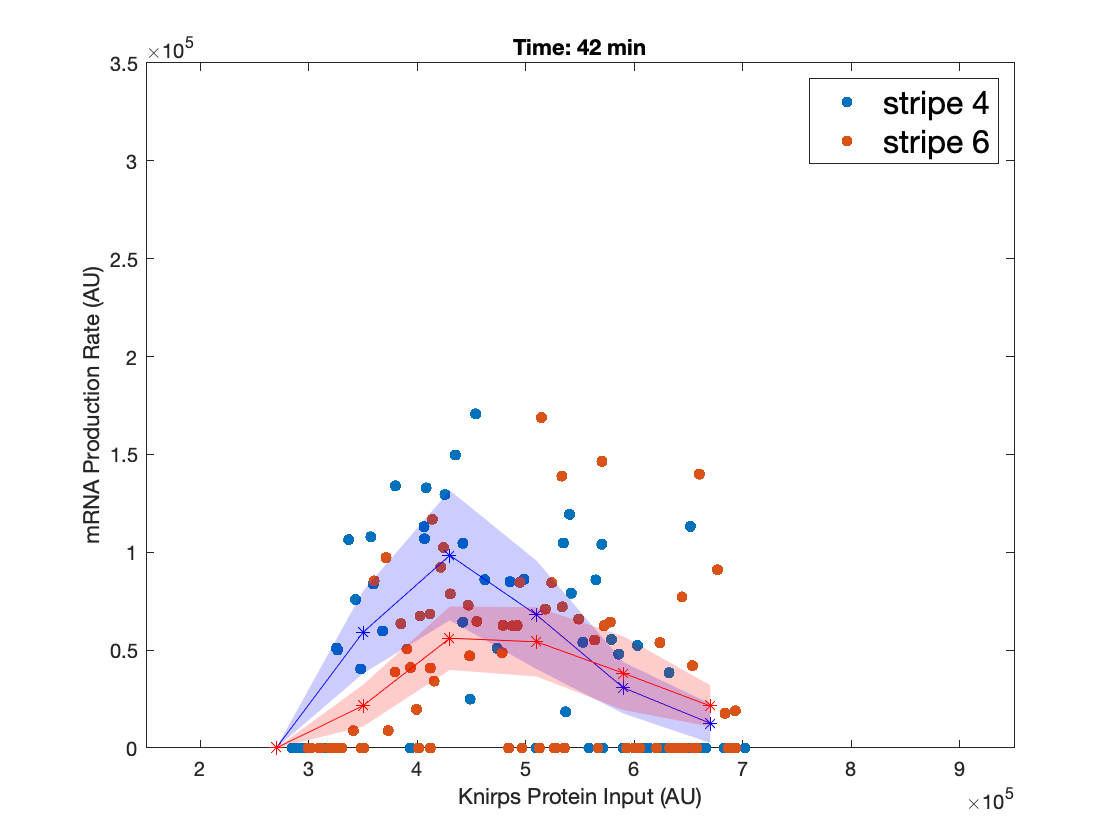

% initialize some parameters
test_frame = 100;

nuclei_stripe4 = [];
nuclei_stripe6 = [];

edges = (1.5:0.8:9.5)*1E5;
len = length(edges)-1;
xmid = 0.5*(edges(1:end-1)+edges(2:end));

% Store calculated results
y4_result = zeros(length(sch_pass),length(xmid));
y6_result = zeros(length(sch_pass),length(xmid));
err4_result = zeros(length(sch_pass),length(xmid));
err6_result = zeros(length(sch_pass),length(xmid));

% Get nuclei for stripe 4
for i = 1:length(sch_pass)
    if (x_pos(i,test_frame)<640) && (x_pos(i,test_frame)>480)
        nuclei_stripe4 = [nuclei_stripe4 i];
    end
end

% Get nuclei for stripe 6
for i = 1:length(sch_pass)
    if (x_pos(i,test_frame)<390) && (x_pos(i,test_frame)>190)
        nuclei_stripe6 = [nuclei_stripe6 i];
    end
end

for i = 1:length(time_point_final)
    
    x4 = nuclei_fluo_avr(nuclei_stripe4,i);
    y4 = spot_fluo_avr(nuclei_stripe4,i);
    
    x6 = nuclei_fluo_avr(nuclei_stripe6,i);
    y6 = spot_fluo_avr(nuclei_stripe6,i);
    
    [~,~,loc4]=histcounts(x4,edges);
    yplot4 = accumarray(loc4(loc4>0),y4(loc4>0),[len 1])./accumarray(loc4(loc4>0),1,[len 1]);
    err4 = sqrt(accumarray(loc4(loc4>0),(y4(loc4>0)).^2,[len 1])./accumarray(loc4(loc4>0),1,[len 1]))./sqrt(accumarray(loc4(loc4>0),1,[len 1]));
    
    [~,~,loc6]=histcounts(x6,edges);
    yplot6 = accumarray(loc6(loc6>0),y6(loc6>0),[len 1])./accumarray(loc6(loc6>0),1,[len 1]);
    err6 = sqrt(accumarray(loc6(loc6>0),(y6(loc6>0)).^2,[len 1])./accumarray(loc6(loc6>0),1,[len 1]))./sqrt(accumarray(loc6(loc6>0),1,[len 1]));
    
    y4_result(i,:) = yplot4;
    y6_result(i,:) = yplot6;
    err4_result(i,:) = err4;
    err6_result(i,:) = err6;
    
    
    fig = figure(5);
    plot(x4,y4,'.','MarkerSize',15)
    hold on
    plot(x6,y6,'.','MarkerSize',15)
    boundedline(xmid, yplot4, err4, '-b*','nan', 'gap','alpha');
    boundedline(xmid, yplot6, err6, '-r*','nan', 'gap','alpha');
    %plot(xmid,y_plot,'-o','LineWidth',2)
    xlim([1.5E5 9.5E5])
    ylim([0 3.5E5])
    title(['Time: ',num2str(time_point_final(i)),' min'])
    xlabel('Knirps Protein Input (AU)')
    ylabel('mRNA Production Rate (AU)')
    legend('stripe 4', 'stripe 6','FontSize',16)
    saveas(fig,[FigPath '/input_output/Frame_',num2str(i),'.jpg'])
    hold off
    
end

## Plot traces for stripe 4 and stripe 6


%{
% For stripe 4
for i = 1:length(nuclei_stripe4)
    
    spot_temp = spot_fluo_traces(nuclei_stripe4(i),:);
    nuclei_temp = nuclei_fluo_traces(nuclei_stripe4(i),:);

    % Interpolate traces
    spot_interp = interp1(x,spot_temp,time_point_final,'pchip');
    nuclei_interp = interp1(x,nuclei_temp,time_point_final,'pchip');

    % pmoving average
    %nuclei_interp_avr = movmean(nuclei_interp,13);
    %spot_interp_avr = movmean(spot_interp,13);
    nuclei_interp_avr = nuclei_interp;
    spot_interp_avr = spot_interp;

    spot_fluo_ins(i,:) = spot_interp;
    nuclei_fluo_ins(i,:) = nuclei_interp;

    % use integrated mRNA level as input
    spot_fluo_avr(i,:) = spot_interp_avr;
    nuclei_fluo_avr(i,:) = nuclei_interp_avr;

    %spot_temp = spot_fluo_output(i,:);
    if sum(spot_temp) > 0
        
        fig = figure(5);
        subplot(1,2,1)
        plot(x,nuclei_temp,'-o',time_point_final,nuclei_interp,'-x');
        hold on
        plot(time_point_final,nuclei_interp_avr,'-','LineWidth',2)
        xlabel('Time (min)')
        ylabel('Fluorescence (AU)')
        xlim([12 48])
        ylim([0 9E5])
        title('Input: Protein Concentration')
        hold off

        subplot(1,2,2)
        plot(x,spot_temp,'-o',time_point_final,spot_interp,'-x');
        hold on
        plot(time_point_final,spot_interp_avr,'-','LineWidth',2)
        xlabel('Time (min)')
        ylabel('Fluorescence (AU)')
        xlim([12 48])
        ylim([0 5E5])
        title('Output: Spot FLuorescence')
        legend('Spot Fluorescence')
        hold off

        saveas(fig,['./figure/stripe4_traces/Particle_',num2str(i),'.jpg'])
    end

end
%}

% For stripe 6
for i = 1:length(nuclei_stripe6)
    
    spot_temp = spot_fluo_traces(nuclei_stripe6(i),:);
    nuclei_temp = nuclei_fluo_traces(nuclei_stripe6(i),:);

    % Interpolate traces
    spot_interp = interp1(x,spot_temp,time_point_final,'pchip');
    nuclei_interp = interp1(x,nuclei_temp,time_point_final,'pchip');

    % pmoving average
    %nuclei_interp_avr = movmean(nuclei_interp,13);
    %spot_interp_avr = movmean(spot_interp,13);
    nuclei_interp_avr = nuclei_interp;
    spot_interp_avr = spot_interp;

    spot_fluo_ins(i,:) = spot_interp;
    nuclei_fluo_ins(i,:) = nuclei_interp;

    % use integrated mRNA level as input
    spot_fluo_avr(i,:) = spot_interp_avr;
    nuclei_fluo_avr(i,:) = nuclei_interp_avr;

    %spot_temp = spot_fluo_output(i,:);
    if sum(spot_temp) > 0
        
        fig = figure(5);
        subplot(1,2,1)
        plot(x,nuclei_temp,'-o',time_point_final,nuclei_interp,'-x');
        hold on
        plot(time_point_final,nuclei_interp_avr,'-','LineWidth',2)
        xlabel('Time (min)')
        ylabel('Fluorescence (AU)')
        xlim([12 48])
        ylim([0 9E5])
        title('Input: Protein Concentration')
        hold off

        subplot(1,2,2)
        plot(x,spot_temp,'-o',time_point_final,spot_interp,'-x');
        hold on
        plot(time_point_final,spot_interp_avr,'-','LineWidth',2)
        xlabel('Time (min)')
        ylabel('Fluorescence (AU)')
        xlim([12 48])
        ylim([0 5E5])
        title('Output: Spot FLuorescence')
        legend('Spot Fluorescence')
        hold off

        saveas(fig,['./figure/stripe6_traces/Particle_',num2str(i),'.jpg'])
    end

end